# Extraction of context-specific models via XomicsToModel

## Author: German Preciat, Analytical BioSciences, Leiden University

## INTRODUCTION

The `XomicsToModel` pipeline${\;}^1$ of the COBRA Toolbox v3.4${\;}^2$, facilitates the generation a thermodynamic-flux-consistent, context-specific, genome-scale metabolic model in a single command by combining a generic model with bibliomic, transcriptomic, proteomic, and metabolomic data. To ensure the network's quality, several thermodynamic consistency checks are implemented within the function. To generate a thermodynamic-flux-consistent, context-specific, genome-scale metabolic model, the function requires three inputs: a generic COBRA model and two variables containing the context-specific data and technical information defined by the user. 

This tutorial shows how to extract a context-specific genome-scale model of a dopaminergic neuron (*iDopaNeuroC*${\;}^3$) from the human generic model Recon3D${\;}^4$ . The *iDopaNeuroC*${\;}^3$ model is extracted using data from manual curation of a dopaminergic neuron to identify active and inactive genes, reactions, and metabolites, as well as information from in vitro experiments such as exometabolomic quantification and transcriptomic sequencing of a cell culture of pluripotent stem cell-derived dopaminergic neurons.

## PROCEDURE

Install MATLAB and then the COBRA Toolbox as described here: [https://opencobra.github.io/cobratoolbox/stable/installation.html](https://opencobra.github.io/cobratoolbox/stable/installation.html)

Select a solver suitable for solving linear (LP) and quadratic (QP) optimisation problems, e.g., mosek, gurobi, ibm_cplex, etc.

[~, ~] = changeCobraSolver('mosek', 'all', 0);

### Generic model

The COBRA model Recon3D${\;}^4$, representing human metabolic reconstruction, a can be found in a file with the extension ".mat". Recon3D${\;}^1$ , which is found in the [VMH](https://www.vmh.life/#downloadview) database${\;}^2$, can be used as a generic model for human metabolism. The thermodynamic consistent human metabolic reconstruction Recon3D${\;}^4$.

global CBTDIR
inputFolder = [CBTDIR filesep 'tutorials' filesep 'dataIntegration'...
filesep 'XomicsToModel' filesep 'iDopaNeuro' filesep 'data' filesep];
genericModelName = 'Recon3DModel_301_xomics_input.mat';
load([inputFolder genericModelName])

### Context-specific data

This type of information represents the biological system's phenotype and can be obtained through a review of the literature or experimental data derived from the biological system. The context-specific data can be loaded from a spreadsheet or added manually. 

#### Automated data integration

Tables or multiple data sets can be inserted in an external worksheet document so that the `preprocessingOmicsModel` function can include them in the `options` variable. The name of the sheet corresponding to the options field must be the same as those specified above and in the manuscript, or they will be omitted.

**Bibliomic** **data. **It is derived from manual reconstruction following a review of the literature. This includes data on the activation or inactivation of genes, reactions, or metabolites. Another example is the addition of coupled reactions or the constraints of different reactions based on phenotypic observations. 

- `specificData.activeGenes:` List of Entrez ID of genes that are known to be active based on the bibliomic data (Default: empty).

- `specificData.addCoupledRxns:` Logical, should the coupled constraints be added (Default: `true`).

- `specificData.coupledRxns:` Logical, indicates whether curated data should take priority over omics data (Default: false).

- `specificData.essentialAA:` List exchange reactions of essential amino acid (Default: empty).

- `specificData.inactiveGenes:` List of Entrez ID of genes known to be inactive based on the bibliomics data (Default: empty).

- `specificData.presentMetabolites:` List of metabolites known to be active based on the bibliomics data (Default: empty).

- `specificData.rxns2add:` Table containing the identifier of the reaction to be added, its name, the reaction formula, the metabolic pathway to which it belongs, the gene rules to which the reaction is subject, and the references. (Default: empty).

- `specificData.rxns2constrain:` Table containing the reaction identifier, the updated lower bound, the updated upper bound, a description for the constraint and notes such as references or special cases (Default: empty).

Manually curated data. To read the table and prepare the variable `specificData` it is used the function `preprocessingOmicsModel`. In this tutorial the bibliomic data is contained in the file *'bibliomicData.xlsx'*.

bibliomicData = 'bibliomicData.xlsx';
specificData = preprocessingOmicsModel([inputFolder bibliomicData], 1, 1);

Reading inputData from : C:\Users\User\work\code\cobratoolbox\cobratoolbox-develop\tutorials\dataIntegration\XomicsToModel\iDopaNeuro\data\bibliomicData.xlsx
Reading sheet: activeGenes
Reading sheet: activeReactions
Reading sheet: cellCultureData
Reading sheet: coupledRxns
Reading sheet: essentialAA
Reading sheet: inactiveGenes
Reading sheet: mediaData
Reading sheet: presentMetabolites
Reading sheet: rxns2add
Reading sheet: rxns2constrain
Reading sheet: rxnsHypothesis
Reading sheet: rxns2remove
Reading sheet: sinkDemand


**Metabolomic data. **Differences in measured concentrations of metabolites within cells, biofluids, tissues, or organisms are translated into flux units of flux ($\mu \textrm{mol}/\textrm{gDW}/h$).

- `specificData.cellCultureData:` Table containing the cell culture data used to calculate the uptake flux. Includes well volume ($L$), time interval cultured ($\textrm{hr}$), average protein concentration ($g/L$), assay volume ($L$), protein fraction ($g/g\;\textrm{dry}\;\textrm{weight}$) , and the sign for uptakes (Default: -1).

- `specificData.exoMet:` Table with the fluxes obtained from exometabolomics experiments. It includes the reaction identifier, the reaction name, the measured mean flux, standard deviation of the measured flux, the flux units, and the platform used to measure it.

- `specificData.mediaData:` Table containing the initial media concentrations. Contains the reaction identifier, the maxiumum uptake ($\mu \textrm{mol}/\textrm{gDW}/h$) based on the concentration of the metabolite and the concentration ($\mu \textrm{mol}$; Default: empty). 

In this tutorial the exometabolomic data is saved in the table 'exoMet'.

specificData.exoMet = readtable([inputFolder 'exometabolomicData.txt']);

**Proteomic data.** This information indicates the level of expression of the proteome. 

- `specificData.proteomics:` Table with a column with Entrez ID's and a column for the corresponding protein levels (Default: empty).

For this tutorial no proteomic data was used.

**Transcriptomic data.** Indicates the level of transcriptome expression and can also be used to calculate reaction expression. Transcriptomic data can be analysed in FPKM.

- `specificData.transcriptomicData:` Table with a column with Entrez ID's and a column for the corresponding transcriptomics expresion value (Default: empty).

In this tutorial the transcriptomic analysis is saved in the table 'transcriptomicData'.

specificData.transcriptomicData = readtable([inputFolder 'transcriptomicData.txt']);
specificData.transcriptomicData.genes = string(specificData.transcriptomicData.genes);

### **Technical parameters**

With these options, technical constraints can be added to the model, as well as setting the parameters for model extraction or debugging.

**Bounds.** They are the instructions that will be set in the boundaries.

- `param.boundPrecisionLimit:` Precision of flux estimate, if the absolute value of the lower bound (`model.lb`) or the upper bound (`model.ub`) are lower than `options.boundPrecisionLimit` but higher than 0 the value will be set to the boundPrecisionLimit (Default: primal feasibility tolerance).

- `param.TolMaxBoundary:` The reaction boundary's maximum value (Default: $1\textrm{e3}$).

- `param.TolMinBoundary:` The reaction boundary's minimum value (Default: $-1\textrm{e3}$).

- `param.relaxOptions:` A structure array with the relaxation options (Default: `param.relaxOptions.steadyStateRelax = 0`). 

param.TolMinBoundary = -1e4;
param.TolMaxBoundary =  1e4;
feasTol = getCobraSolverParams('LP', 'feasTol');
param.boundPrecisionLimit = feasTol * 10;

**Exchange reactions.** They are the instructions for the exchange, demand, and sink reactions.

- `param.addSinksexoMet:` Logical, should sink reactions be added for metabolites measured in the media but without existing exchange reaction (Default: false). 

- `param.closeIons:` Logical, it determines whether or not ion exchange reactions are closed. (Default: false). 

- `param.closeUptakes:` Logical, decide whether or not all of the uptakes in the generic model will be closed (Default: false).

- `param.nonCoreSinksDemands:` The type of sink or demand reaction to close is indicated by a string (Possible options: `'closeReversible'`,  `'closeForward'`,  `'closeReverse'`, `'closeAll'` and `'closeNone'`; Default: `'closeNone'`).

param.closeIons = true; 
param.closeUptakes = true;
param.nonCoreSinksDemands = 'closeAll';
param.sinkDMinactive = true;

**Extraction options.** The solver and parameters for extracting the context-specific model.

- `param.activeGenesApproach:` String with the name of the active genes approach will be used (Possible options: `'oneRxnsPerActiveGene'` or `'deletModelGenes'`; Default: `'oneRxnsPerActiveGene'`).

- `param.fluxCCmethod:` String with thee name of the algorithm to be used for the flux consistency check (Possible options: `'swiftcc'`, `'fastcc'` or `'dc'`, Default: `'fastcc'`).

- `param.fluxEpsilon:` Minimum non-zero flux value accepted for tolerance (Default: Primal feasibility tolerance). 

- `param.thermoFluxEpsilon:` Flux epsilon used in `'thermoKernel'` (Default: feasibility tolerance).

- `param.tissueSpecificSolver:` The name of the solver to be used to extract the context-specific model (Possible options: `'thermoKernel'` and `'fastcore'`; Default: `'thermoKernel'`). 

param.activeGenesApproach = 'oneRxnPerActiveGene';
param.tissueSpecificSolver = 'thermoKernel'; 
param.fluxEpsilon = feasTol * 10;
param.fluxCCmethod = 'fastcc';

**Data-specific parameters. **Parameters that define the minimum level of transcript/protein to be considered as present in the network (treshold) and weather the transcripts below the set treshold should be removed from the model.

- `param.addCoupledRxns:` Logical, should the coupled constraints be added (Default: false). **! CAUTION** If it is TRUE and the table coupledRxns is empty, the step is not performed.

- `param.curationOverOmics:` Logical, indicates whether curated data should take priority over omics data (Default: false).

- `param.inactiveGenesTranscriptomics:` Logical, indicate if inactive genes in the transcriptomic analysis should be added to the list of inactive genes (Default: true).

- `param.metabolomicWeights:` String indicating the type of weights to be applied for metabolomics fitting (Possible options: `'SD'`, `'mean'` and `'RSD'`; Default: `'SD'`).

- `param.setObjective:` Linear objective function to optimise (Default: empty).

- `param.tresholdP:` The proteomic cutoff threshold (in linear scale) for determining whether or not a gene is active (Default: $0$).

- `param.transcriptomicThreshold:` The transcriptomic cutoff threshold (in logarithmic scale) for determining whether or not a gene is active (Default: $0$)

- `param.weightsFromOmics:` Should gene weights be assigned based on the omics data (Default: 0).

param.activeOverInactive = 1;
param.addCoupledRxns = 1;
param.curationOverOmics = false;
param.inactiveGenesTranscriptomics = true; 
param.metabolomicWeights='mean';
param.transcriptomicThreshold = 2; 
param.weightsFromOmics = true;

**Debugging options. **The user can specify the function's verbosity level as well as save the results of the various blocks of the function for debugging.

- `param.debug:` Logical, should the function save its progress for debugging (Default: false).

- `param.diaryFilename:` Location where the output be printed in a diary file (Default: 0).

- `param.printLevel:` Level of verbose that should be printed (Default: 0).

param.printLevel = 1;
param.debug = true;
if isunix()
    name = getenv('USER');
else
    name = getenv('username');
end
param.diaryFilename = [pwd filesep datestr(now,30) '_' name '_diary.txt'];

### XomicsToModel function

XomicsToModel run, beginning at:01-Apr-2024 14:02:56
--------------------------------------------------------------
 
XomicsToModel input specificData:
 
             inputData: 'C:\Users\User\work\code\cobratoolbox\cobratoolbox-develop\tutorials\dataIntegration\XomicsToModel\iDopaNeuro\data\bibliomicData.xlsx'
           activeGenes: {239×1 cell}
       activeReactions: {334×1 cell}
       cellCultureData: [1×6 table]
           coupledRxns: [11×5 table]
           essentialAA: [9×1 table]
         inactiveGenes: {61×1 cell}
             mediaData: [56×3 table]
    presentMetabolites: [45×4 table]
              rxns2add: [21×9 table]
        rxns2constrain: [48×5 table]
        rxnsHypothesis: [33×5 table]
           rxns2remove: [233×5 table]
            sinkDemand: [49×8 table]
                exoMet: [49×13 table]
    transcriptomicData: [18530×2 table]

XomicsToModel input param:
 
                      TolMinBoundary: -10000
                      TolMaxBoundary: 10000
           

problemRxnList = 5×1 cell array
    {'ATPS4mi'    }
    {'CYOOm2i'    }
    {'CYOOm3i'    }
    {'CYOR_u10mi' }
    {'NADH2_u10mi'}


fixed rxn list:


fixedRxnList = 5×1 cell array
    {'ATPS4minew'    }
    {'CYOOm2inew'    }
    {'CYOOm3inew'    }
    {'CYOR_u10minew' }
    {'NADH2_u10minew'}


 
Feasible generic input model.
 
--------------------------------------------------------------
 
Generating model without an objective function.
 
 
--------------------------------------------------------------
Adding 21 reactions ...
 
Reaction boundaries not provided. Default (min and max) values will be used based on the reaction formula.
acleua	h2o[c] + acleu_L[c] 	->	ac[c] + leu_L[c] 
acthra	h2o[c] + acthr_L[c] 	->	ac[c] + thr_L[c] 
acileua	h2o[c] + acile_L[c] 	->	ac[c] + ile_L[c] 
acglua	h2o[c] + acglu[c] 	->	glu_L[c] + ac[c] 
CE1554tm	CE1554[c] 	<=>	CE1554[m] 
RE2031M	accoa[m] + ala_L[m] 	<=>	h[m] + coa[m] + CE1554[m] 
RE2642C	h2o[c] + CE1554[c] 	<=>	ac[c] + ala_L[c] 
CE1554t	CE1554[c] 	<=>	CE1554[e] 
EX_CE1554[e]	CE1554[e] 	<=>	
DM_ps_hs[c]	ps_hs[c] 	<=>	
CYSTS_H2S	cys_L[c] + hcys_L[c] 	<=>	HC00250[c] + cyst_L[c] 
DHBOX	h2o2[c] + quinonemethide[c] 	->	3,4-dihydroxybenzaldehyde[c] + methanimine[c] 
DM_clpn_hs[c]	clpn_hs[c] 	->	
EX_adocbl[e]	adocbl[e] 	<=>	
EX_ca2[e]	ca2[e] 	<

0 deleted non-core metabolites,  corresponding to thermodynamic flux inconsistency.
0 deleted core metabolites,  corresponding to thermodynamic flux inconsistency.
0 deleted non-core reactions,  corresponding to thermodynamic flux inconsistency.
7 deleted core reactions,  corresponding to thermodynamic flux inconsistency.
    Forward_Reaction, 0 bound                     Name                     lb           ub                              equation                   
    _________________________    ______________________________________    __    _________________    _____________________________________________

            {'r0160'}            {'L-Serine:Pyruvate Aminotransferase'}    0     0.287664767381492    {'pyr[c] + ser_L[c]  -> ala_L[c] + hpyr[c] '}

    Forward_Reaction, non-0 bound          

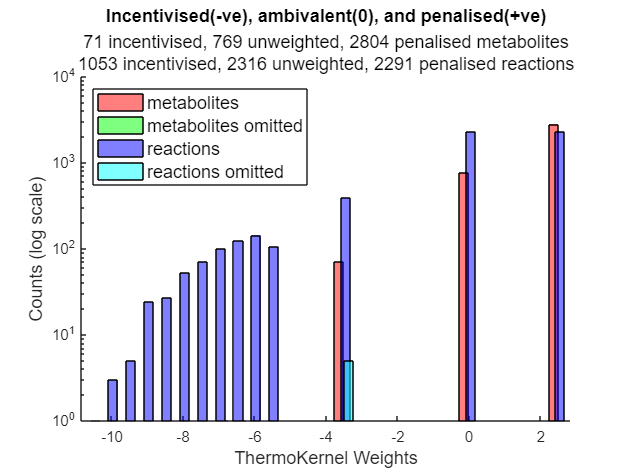

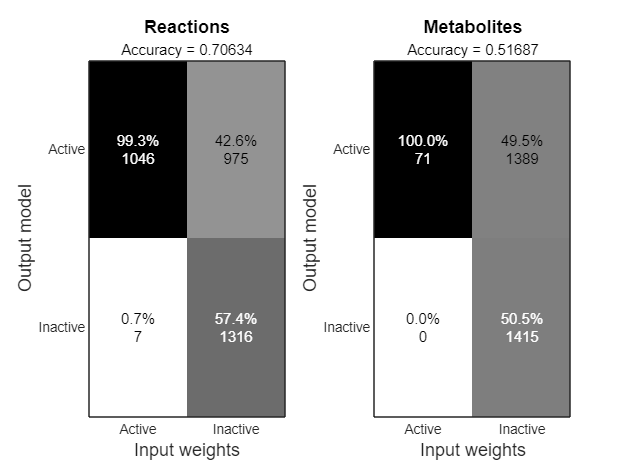

2089 deleted non-core metabolites,  corresponding to removal by createTissueSpecificModel.
0 deleted core metabolites,  corresponding to removal by createTissueSpecificModel.
3097 deleted non-core reactions,  corresponding to removal by createTissueSpecificModel.
5 deleted core reactions,  corresponding to removal by createTissueSpecificModel.
    Forward_Reaction, non-0 bound               Name                         lb              ub                                    equation                               
    _____________________________    ___________________________    ____________________    _____    _____________________________________________________________________

          {'GBAl'        }           {'Glucosylceramidase'     }                  0.0001     1000    {'h2o[l] + gluside_hs[l]  -> crm_hs[l] +

[iDopaNeuro, modelGenerationReport] = XomicsToModel(model, specificData, param);

## Examining when active metabolites, reactions and genes were added or removed during the model generation process

debugXomicsToModel(model, pwd, modelGenerationReport)

#Active_genes               #Active_rxns              #Active_mets                Stage
          909                        432                        43                Active list
#Active_genes #Model_genes  #Active_rxns #Model_rxns  #Active_mets #Model_mets    lb_obj    Obj  Message    Stage
          885         2248           401       10600            43        5835        0  755.003 Feasible    Generic model
          882         1892           424       10617            43        5840         NaN           0 Feasible    5.debug_prior_to_setting_default_min_and_max_bounds.mat
          882         1892           424       10617            43        5840         NaN           0 Feasible    8.debug_prior_to_exchange_constraints.mat
          882         1892           424       10617            43        5840         NaN           0 Feasible    10.a.debug_prior_to_media_constraints.mat
          882         1892           424       10617            43        5840         NaN      

## TIMING

TIMING: 15 minutes to hours (computation) - days (interpretation)

## Bibliography

- German Preciat, Agnieszka B. Wegrzyn, Ines Thiele, et al., "XomicsToModel: a COBRA Toolbox extension for generation of thermodynamic-flux-consistent, context-specific, genome-scale metabolic models", *bioRxiv* (**2021**)

- Laurent Heirendt, Sylvain Arreckx, Thomas Pfau, et al., "Creation and analysis of biochemical constraint-based models using the COBRA Toolbox v. 3.0", *Nature protocols* (**2019**).

- German Preciat, Edinson Lucumi Moreno, Agnieszka B. Wegrzyn, et al., "Mechanistic model-driven exometabolomic characterisation of human dopaminergic neuronal metabolism", *bioRxiv* (**2021**)

- Elizabeth Brunk, Swagatika Sahoo, Daniel C. Zielinski, et al., "Recon3D enables a three-dimensional view of gene variation in human metabolism", *Nature biotechnology *(**2018**)